syms v(t) t k m V0

v(t) = sqrt(m*9.8/k)*tan(-9.8*t/sqrt(m*9.8/k) + atan(V0/sqrt(m*9.8/k)))

$$v(t) = \tan\left(\mathrm{atan}\left(\frac{V_{0}}{\sqrt{\frac{49\,m}{5\,k}}}\right)-\frac{49\,t}{5\,\sqrt{\frac{49\,m}{5\,k}}}\right)\,\sqrt{\frac{49\,m}{5\,k}}$$

tend = (solve(v(t) == 0,t))

$$tend = \frac{5\,\mathrm{atan}\left(\frac{V_{0}}{\sqrt{\frac{49\,m}{5\,k}}}\right)\,\sqrt{\frac{49\,m}{5\,k}}}{49}$$


dhtemp(t) = (int(v(t),t));

$$dhtemp(t) = \frac{m\,\log\left(7\,\cos\left(\frac{7\,\sqrt{5}\,t}{5\,\sqrt{\frac{m}{k}}}\right)\,\sqrt{\frac{m}{k}}+\sqrt{5}\,V_{0}\,\sin\left(\frac{7\,\sqrt{5}\,t}{5\,\sqrt{\frac{m}{k}}}\right)\right)}{k}$$


dh = dhtemp(tend) - dhtemp(0)

$$dh = \begin{array}{l} \frac{m\,\log\left(7\,\cos\left(\sigma_{1}\right)\,\sqrt{\frac{m}{k}}+\sqrt{5}\,V_{0}\,\sin\left(\sigma_{1}\right)\right)}{k}-\frac{m\,\log\left(7\,\sqrt{\frac{m}{k}}\right)}{k}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{5}\,\mathrm{atan}\left(\frac{V_{0}}{\sqrt{\frac{49\,m}{5\,k}}}\right)\,\sqrt{\frac{49\,m}{5\,k}}}{7\,\sqrt{\frac{m}{k}}} \end{array}$$


v(t) = subs(v(t),[V0 m k],[500 200 10])

$$v(t) = -14\,\tan\left(\frac{7\,t}{10}-\mathrm{atan}\left(\frac{250}{7}\right)\right)$$

tend = double(subs(tend,[V0 m k],[500 200 10]))

tend = 2.2040

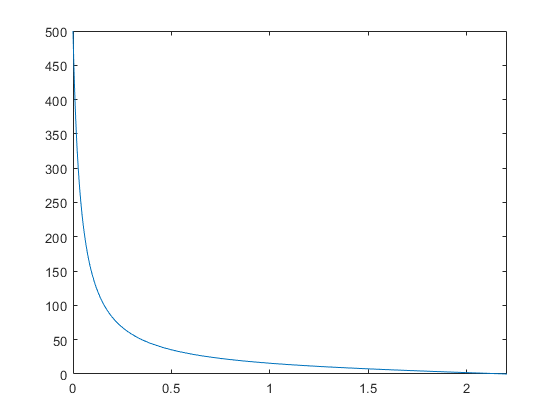




fplot(v(t),[0 tend])